clear;clc;close all
layerfolder='../data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 6.316397 seconds.


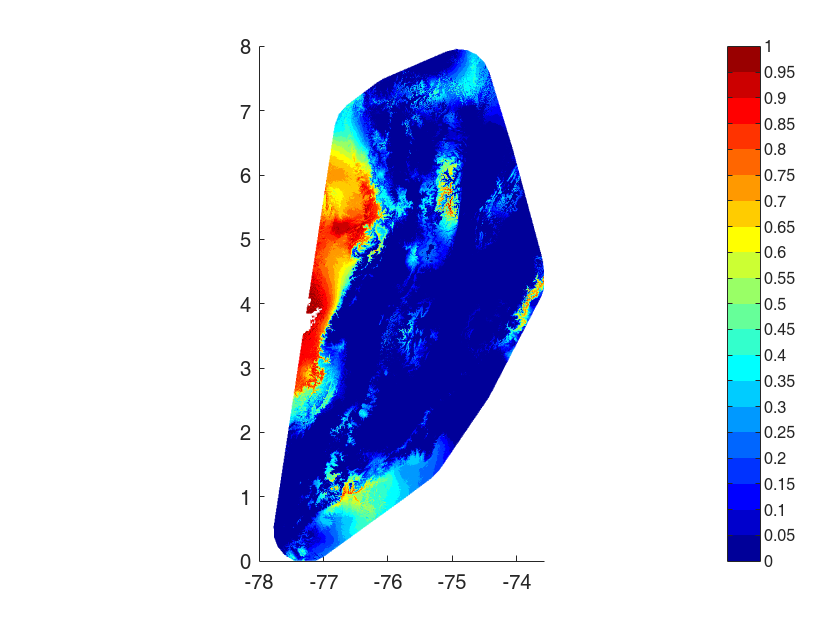

InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

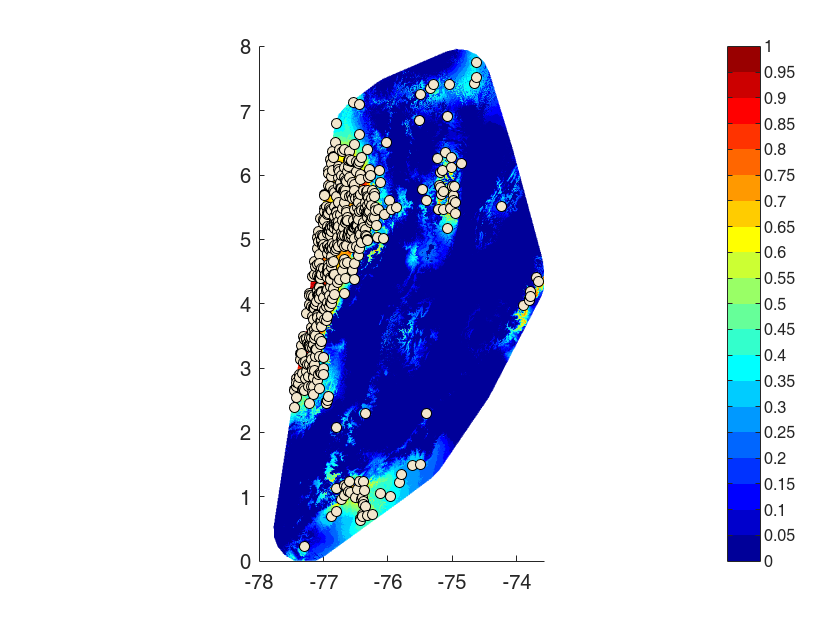

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 500, -3, true, 'GenSP', true, true);

----Finding clusters----


1 clusters identified


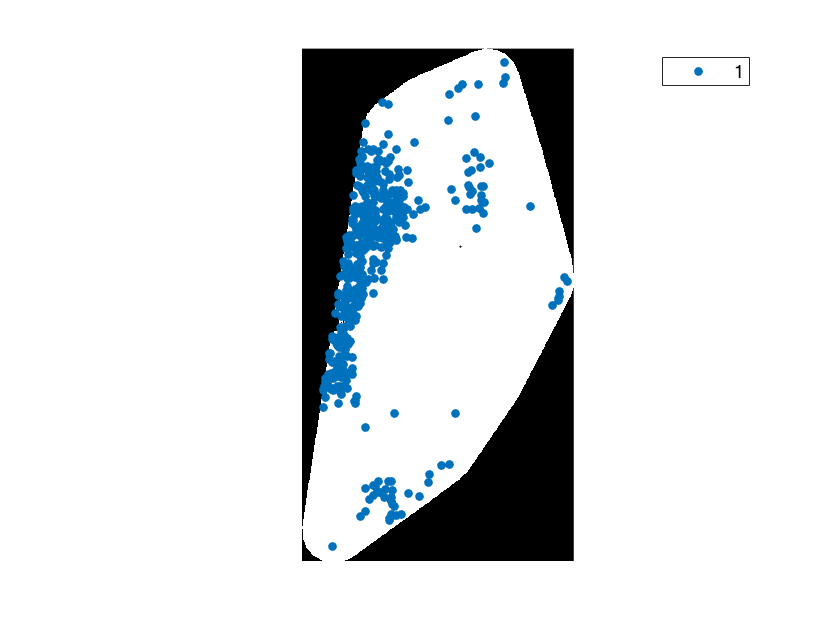

Elapsed time is 2.999790 seconds.
----Finding correlation----
Elapsed time is 8.100116 seconds.
----Creating predictors----
¡All done!
Elapsed time is 8.415919 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false);

data{1}

dataf = bnm_modeling(data, '', true, 4, false);

close all
show=true; %show graphics
outlier=false; %remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true; %remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
datab = bnm_modeling2(data{1},show,outlier,outlier2)

Brace indexing is not supported for variables of
this type.

Error in pcaO (line 24)
pin=data{:,:}*coeff(:,1:3);

Error in bnm_modeling2 (line 27)
[map3,score]=pcaO(T2,Z,R,indicators,vars,show,false,false);

clf
x = rand(25,1);
y = rand(25,1);
z = rand(25,1);
k = boundary(x,y,z,0);
trisurf(k,x,y,z, 'Facecolor','cyan','FaceAlpha',0.8); axis equal;
hold on
plot3(x,y,z,'.r')
unique(k)

shp=alphaShape(x(k),y(k),z(k));